clear

# Transmission Lines

## Criteria for Transmission Lines

We have input signal called $V_{{\textrm{AA}}^{\prime } }$ denoted by the following equation:


$$V_{{\mathrm{AA}}^{\prime } } =V_g \left(t\right)=V_0 \cos \left(\omega t\right)$$


There will be a propagation delay, because it takes time for signals to travel. The received signal will look something like this


$$V_{{\mathrm{BB}}^{\prime } } =V_{{\mathrm{AA}}^{\prime } } \left(t-\frac{l}{c}\right)=V_0 \cos \left(\omega \left(t-\frac{l}{c}\right)\right)=V_0 \cos \left(\omega t-\phi_0 \right)$$



$$\phi_0 =2\pi \frac{l}{\lambda }$$


syms psi_0(l, lambda)
psi_0(l, lambda) = 2*pi*(l/lambda)

$$psi\_0(l, lambda) = \frac{2\,\pi \,l}{\lambda }$$

$\phi_0$ should be low, or else we treat the system like a transmission line.

## Types of Transmission Lines

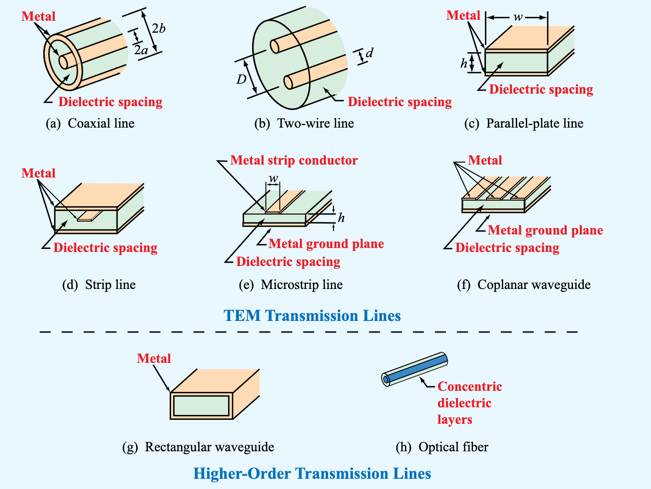

TEM lines can be represented as this

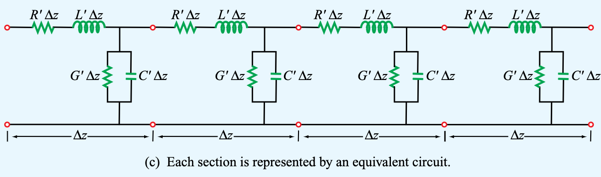

The electrical paramters of the materials that constitute these transmission lines are:

$\mu_c$ - magnetic permeability of conductor

$\sigma_c$ - electrical conductivity of conductor

$\mu$ - magnetic permeability of insulator

$\epsilon$ - electrical permittivity of insulator

$\sigma$ - electrical conductivity of insulator

The values of this lumped-circuit model can be defined as:

$R^{\prime }$ - the combines resistance of both conducters per unit length ($\Omega$/m)

$L^{\prime }$ - the combined inductance of both conducters per unit length (H/m)

$G^{\prime }$ - the conductance of the insulation mediumn between the two conductors (S/m)

$C^{\prime }$ - the capacitance between the two conductors (F/m)

The parameters for the three different TEM lines in focus are:

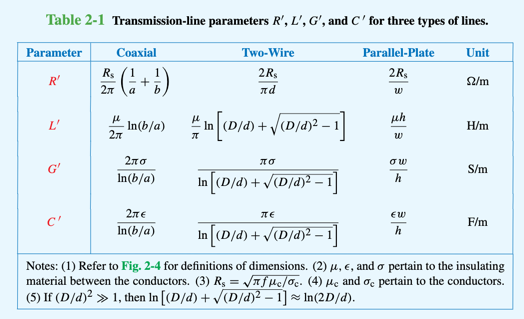

syms R_s(f, mu_c, sigma_c)
R_s(f, mu_c, sigma_c) = sqrt(pi*f*mu_c/sigma_c)

$$R\_s(f, mu\_c, sigma\_c) = \sqrt{\pi }\,\sqrt{\frac{f\,\mu_{c}}{\sigma_{c}}}$$

Coaxial Line

- $a$  - outer radius of inner condutor (m)

- $b$  - inner radius of outer conducter (m)

syms coaxialR(R_sval, a, b)
coaxialR(R_sval, a, b) = (R_sval/(2*pi))*((1/a)+(1/b))

$$coaxialR(R\_sval, a, b) = \frac{R_{\mathrm{sval}}\,\left(\frac{1}{a}+\frac{1}{b}\right)}{2\,\pi }$$


syms coaxialL(mu, a, b)
coaxialL(mu, a, b) = (mu/(2*pi))*log(b/a)

$$coaxialL(mu, a, b) = \frac{\mu \,\log\left(\frac{b}{a}\right)}{2\,\pi }$$


syms coaxialG(sigma, a, b)
coaxialG(sigma, a, b) = (2*pi*sigma)/log(b/a)

$$coaxialG(sigma, a, b) = \frac{2\,\pi \,\sigma }{\log\left(\frac{b}{a}\right)}$$


syms coaxialC(epsilon, a, b)
coaxialC(epsilon, a, b) = (2*pi*epsilon)/log(b/a)

$$coaxialC(epsilon, a, b) = \frac{2\,\pi \,\epsilon }{\log\left(\frac{b}{a}\right)}$$

Two-wire Line

- $d$ - diameter of each wire (m)

- $D$ - spacing between two wire's centers (m)

syms twowireR(R_sval, d)
coaxialR(R_sval, d) = (2*R_sval)/(pi*d)

$$coaxialR(R\_sval, d) = \frac{2\,R_{\mathrm{sval}}}{d\,\pi }$$


syms twowireL(mu, d, D)
coaxialL(mu, d, D) = (mu/pi)*log((D/d)+sqrt((D/d)^2-1))

$$coaxialL(mu, d, D) = \frac{\mu \,\log\left(\frac{\text{D}}{d}+\sqrt{\frac{{\text{D}}^{2}}{d^{2}}-1}\right)}{\pi }$$


syms twowireG(sigma, d, D)
coaxialG(sigma, a, b) = (pi*sigma)/log((D/d)+sqrt((D/d)^2-1))

$$coaxialG(sigma, a, b) = \frac{\pi \,\sigma }{\log\left(\frac{\text{D}}{d}+\sqrt{\frac{{\text{D}}^{2}}{d^{2}}-1}\right)}$$


syms twowireC(epsilon, d, D)
coaxialC(epsilon, a, b) = (pi*epsilon)/log((D/d)+sqrt((D/d)^2-1))

$$coaxialC(epsilon, a, b) = \frac{\pi \,\epsilon }{\log\left(\frac{\text{D}}{d}+\sqrt{\frac{{\text{D}}^{2}}{d^{2}}-1}\right)}$$

Parallel-plate line

- $w$ - width of each plate (m)

- $h$ - thickness of insumation between plates (m)

syms pplateR(R_sval, w)
pplateR(R_sval, w) = (2*R_sval)/w

$$pplateR(R\_sval, w) = \frac{2\,R_{\mathrm{sval}}}{w}$$


syms pplateL(mu, w, h)
pplateL(mu, w, h) = (mu*h)/w

$$pplateL(mu, w, h) = \frac{h\,\mu }{w}$$


syms pplateG(sigma, w, h)
pplateG(sigma, w, h) = (sigma*w)/h

$$pplateG(sigma, w, h) = \frac{\sigma \,w}{h}$$


syms pplateC(epsilon, w, h)
pplateC(epsilon, w, h) = (epsilon*w)/h

$$pplateC(epsilon, w, h) = \frac{\epsilon \,w}{h}$$

## Propagation Constant


$$\gamma =\sqrt{\left(R^{\prime } +i\omega L^{\prime } \right)\left(G^{\prime } +j\omega C^{\prime } \right)}$$


attentuation constant - $\alpha =\mathrm{Re}\left(\gamma \right)$

phase constant - $\beta =\mathrm{Im}\left(\gamma \right)$

syms gamma(R, L, G, C, w)
gamma(R, L, G, C, w) = sqrt((R+1i*w*L)*(G+1i*w*C))

$$gamma(R, L, G, C, w) = \sqrt{\left(G+C\,w\,\mathrm{i}\right)\,\left(R+L\,w\,\mathrm{i}\right)}$$

## Characteristic Impedance


$$Z_0 =\frac{R^{\prime } +j\omega L^{\prime } }{\gamma }=\sqrt{\frac{R^{\prime } +j\omega L^{\prime } }{G^{\prime } +j\omega C^{\prime } }}$$


syms Z_0(R, L, G, C, w)
Z_0(R, L, G, C, w) = sqrt((R+1i*w*L)/(G+1i*w*C))

$$Z\_0(R, L, G, C, w) = \sqrt{\frac{R+L\,w\,\mathrm{i}}{G+C\,w\,\mathrm{i}}}$$